% Load a training data table
load("allData.mat");
[trainingData,~] = splitData(allData,0.8);

imageSize = [1024 1024 3];
numClasses = 1;
anchorBoxes = [1 1;4 6;5 3;9 6];
network = resnet50();
featureLayer = 'activation_49_relu';
lgraph = yolov2Layers(imageSize,numClasses,anchorBoxes,network,featureLayer);
%analyzeNetwork(lgraph)

options = trainingOptions("sgdm", ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.2, ...
    LearnRateDropPeriod=5, ...
    MaxEpochs=5, ...
    MiniBatchSize=5, ...
    Plots="training-progress");

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* bbox

Checking training data...done.
在单 GPU 上训练。
正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　小批量损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０９　｜　　　　　　３９．５６　｜　　１５６４．９　｜　　０．０１００　｜
｜　　　１　｜　　　５０　｜　　　　　００：０８：０７　｜　　　　　　２３．２９　｜　　　５４２．５　｜　　０．０１００　｜
｜　　　２　｜　　１００　｜　　　　　００：１６：１２　｜　　　　　　２５．１６　｜　　　６３３．３　｜　　０．０１００　｜
｜　　　３　｜　　１５０　｜　　　　　００：２４：１４　｜　　　　　　２２．７１　｜　　　５１５．７　｜　　０．０１００　｜
｜　　　４　｜　　２００　｜　　　　　００：３２：１９　｜　　　　　　２３．９６　｜　　　５７４．１　｜　　０．０１００　｜
｜　　　５　｜　　２５０　｜　　　　　００：４０：１７　｜　　　　　　２４．１０　｜　　　５８１．０　｜　　０．０１００　｜
｜　　　５　｜　　２５５　｜　　　　　００：４１：０４　｜　　　　　　２３．１４　｜　　　５３５．３　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
训练结束: 已完成最大轮数。


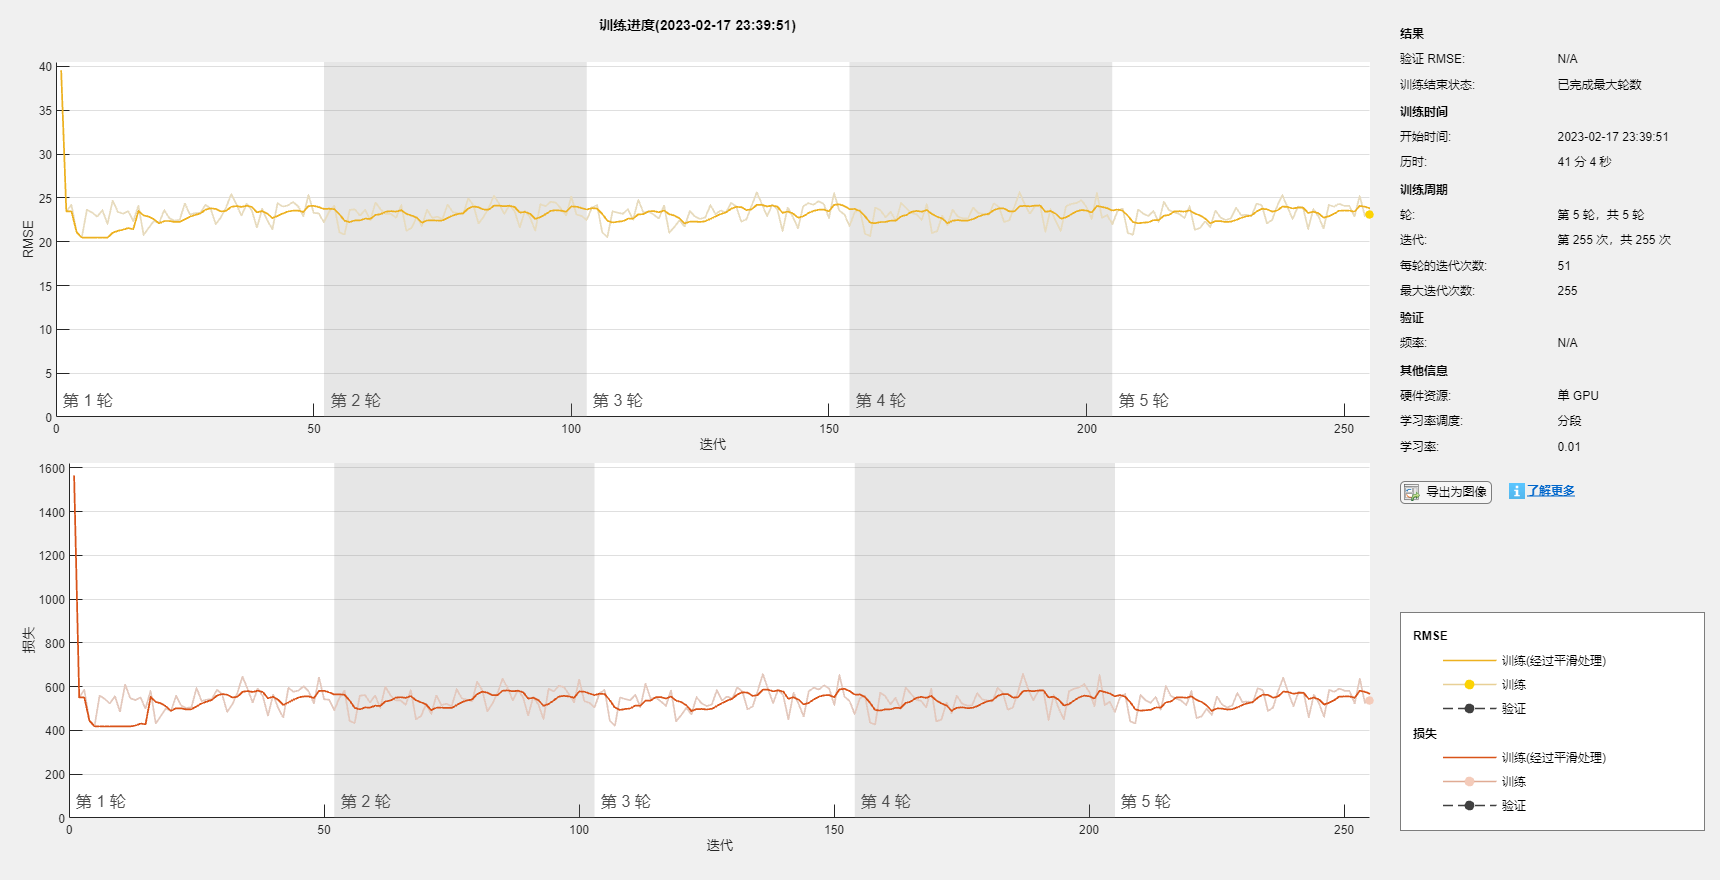

Detector training complete.
*************************************************************************



% Train YOLOv2 network
Yolov2Detector = trainYOLOv2ObjectDetector(trainingData,lgraph,options);